Improved DETM: continuous V

clear all;
global A B K H1 alpha delta beta eta epsilon tau delta_max delta_min P
A = [1 1; 0 1];
B = [0; 1];
D1 = diag([2.5 0 1 0 0 1 0 0 0 2]);
W1 = [0 1 2 0 0 0 0 0 0 0;
    1 0 0 1.5 0 0 0 0 0 0;
    2 0 0 0 0.5 0 0 0 0 0;
    0 1.5 0 0 0 0 0 0 0 0;
    0 0 0.5 0 0 0 0 0 2 0;
    0 0 0 0 0 0 1 3 0 0;
    0 0 0 0 0 1 0 0 1.5 0;
    0 0 0 0 0 3 0 0 0 1;
    0 0 0 0 2 0 1.5 0 0 0;
    0 0 0 0 0 0 0 1 0 0];
L1 = -W1 + diag(sum(W1, 2)); % Laplacien matrix
H1 = L1+D1;
P = [23 9.5; 9.5 8];
K = B'*P;

% parameters
delta_min = min(eig(H1));
delta_max = max(eig(H1));
alpha = abs(max( eig((P*A+A'*P)/2) ) );
epsilon = abs(max( eig((A+A')/2) ) );
beta = max(eig(P*(B*B')*P));
delta = max(eig(H1));
eta = min(eig(P));
tau = 1;
y_bar = 1;


% leader
x0_initial = [1;1];
y_initial = y_bar*ones(10,1);

% followers
x_initial =  zeros(20,1);
for i=1:10
    x_initial(2*i-1: 2*i) = [0.5*i+10; i+2.5];
end
xi_initial = x_initial - kron(ones(10,1), x0_initial);
e_initial = kron(ones(10,1), [0;0]);
s_initial = [xi_initial; e_initial; y_initial];
times_trigger = zeros(10,1);

%odeoptions = odeset('Events',@DETM_events,'RelTol',1e-1,'OutputFcn',@odeplot,'OutputSel',[1:2:20]);
odeoptions = odeset('Events',@DETM_events);

tstart = 0;
tfinal = 1; % 仿真时长
tout = zeros(1e6,1);
sout = zeros(1e6,50);
% tout = [];
% sout = [];
% teout = [];
% yeout = [];
% ieout = [];

f = waitbar(0,'Simulation');
ite = 2;
while tstart < tfinal
    waitbar(tstart/tfinal,f,sprintf('Simulation: %.4f s/%.4f s',tstart, tfinal));
    
    % solver: ode15s: stiffness
    % ode45: non-stiffness
    ETM_strategy = @(t,x) DETM3_dynamic(t,x);
    [t_history, s_history,te,ye,ie] = ode15s(ETM_strategy, [tstart, tfinal], s_initial, odeoptions);

    len = length(t_history);
    tout(ite:ite+len-1, :) = t_history(1:end);
    sout(ite:ite+len-1, :) = s_history(1:end,:);
%     tout = [tout; t_history(1:end)];
%     sout = [sout; s_history(1:end,:)];
%     teout = [teout; te];          % Events at tstart are never reported.
%     yeout = [yeout; ye];
%     ieout = [ieout; ie];

    s_initial = s_history(end,:);
    %t_index = [];
    for i = 1:10
        if s_history(end,40+i) <= 0
            %t_index = [t_index i];
            s_initial(20+2*i-1 : 20+2*i) = [0 0];
            s_initial(40+i) = y_bar;
            times_trigger(i) = times_trigger(i) + 1;
        end
    end

    tstart = t_history(end);

    %disp(tstart)
    %disp(t_index)
    ite = ite + len;
end
close(f)
disp(tfinal/min(times_trigger)*1000)

   32.2581



disp(tfinal/max(times_trigger)*1000)

   19.2308



disp(tfinal/mean(times_trigger)*1000)

   21.8341



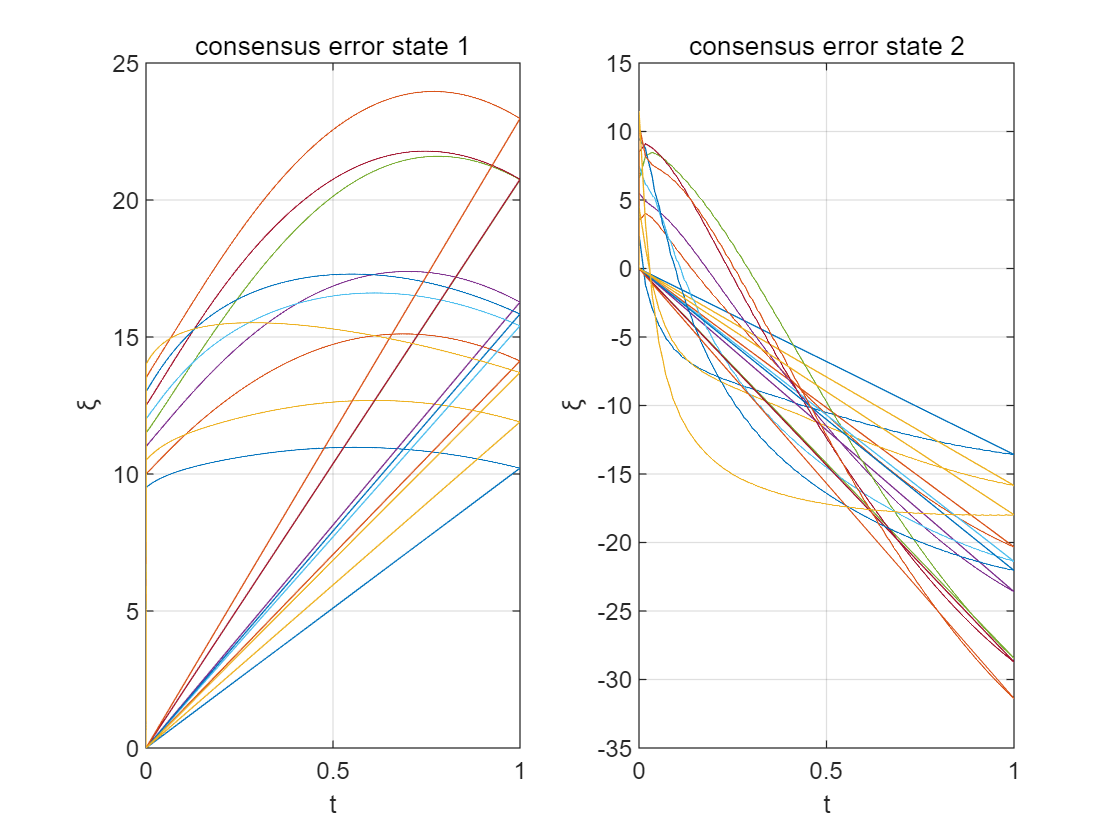

xi_history = sout(:,1:20);
% consensus error
figure()
subplot(1,2,1)
plot(tout, xi_history(:, 1:2:20))
title("consensus error state 1")
xlabel('t')
ylabel('\xi')
grid on

subplot(1,2,2)
plot(tout, xi_history(:,2:2:20))
title("consensus error state 2")
xlabel('t')
ylabel('\xi')
grid on

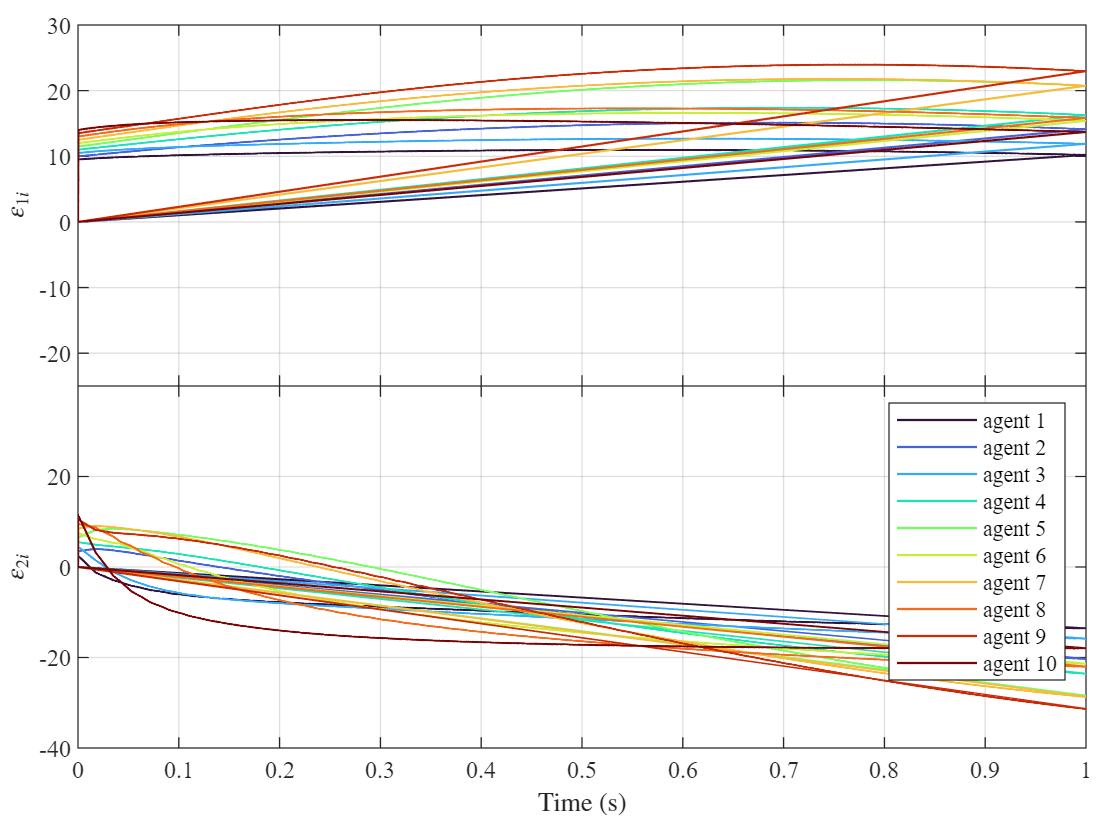

xi_history = sout(:,1:20);
e_history = sout(:,21:40);
figure()
ywidth = 0.43;
cmap = turbo(10);
subplot(2,1,1)
for i = 1:10
plot(tout, xi_history(:,2*i-1),"Color",cmap(i,:),'LineWidth',0.8)
hold on
end
hold off
grid on
set(gca, 'Fontname', 'Times New Roman', 'Fontsize',9)
set(gca,'position',[0.07 0.54 0.9 ywidth])
set(gca,'xticklabel',[]);
set(gca,'ytick',[-20 -10 0 10 20 30]);
ylim([-25 30])
ylabel(' $\varepsilon_{1i}$ ','interpreter','latex')


subplot(2,1,2)
for i = 1:10
plot(tout, xi_history(:,2*i),"Color",cmap(i,:),'LineWidth',0.8)
hold on
end
hold off
grid on
set(gca, 'Fontname', 'Times New Roman', 'Fontsize',9)
set(gca,'position',[0.07 0.54-ywidth 0.9 ywidth])
set(gca,'ytick',[-40  -20  0  20]);
ylim([-40 40])
xlabel("Time (s)",'interpreter','latex')
ylabel(' $\varepsilon_{2i}$ ','interpreter','latex')
legend('agent 1','agent 2','agent 3','agent 4','agent 5','agent 6','agent 7','agent 8','agent 9','agent 10')

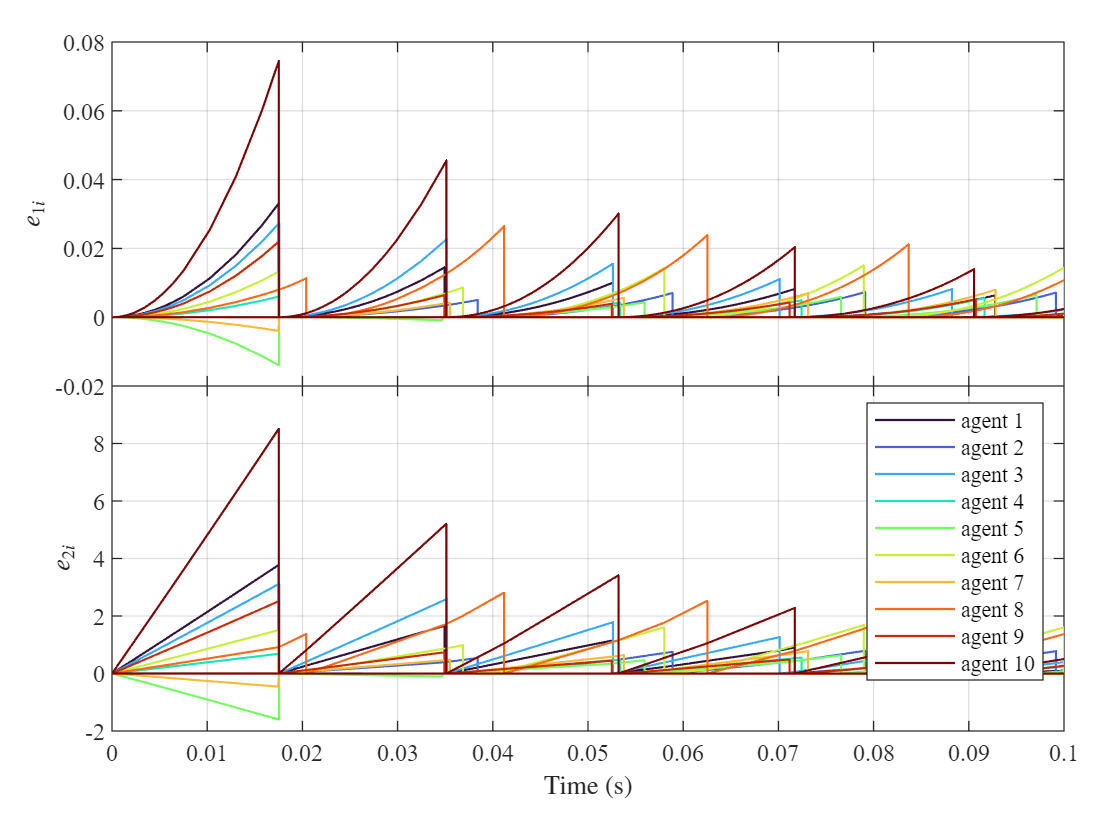


figure()
ywidth = 0.41;
cmap = turbo(10);
subplot(2,1,1)
for i = 1:10
plot(tout, e_history(:,2*i-1),"Color",cmap(i,:),'LineWidth',0.8)
hold on
end
hold off
grid on
set(gca, 'Fontname', 'Times New Roman', 'Fontsize',9)
set(gca,'position',[0.1 0.54 0.85 ywidth])
set(gca,'xticklabel',[]);
%set(gca,'ytick',[-20 -10 0 10 20 30]);
xlim([0 0.1])
ylabel(' $e_{1i}$ ','interpreter','latex')


subplot(2,1,2)
for i = 1:10
plot(tout, e_history(:,2*i),"Color",cmap(i,:),'LineWidth',0.8)
hold on
end
hold off
grid on
set(gca, 'Fontname', 'Times New Roman', 'Fontsize',9)
set(gca,'position',[0.1 0.54-ywidth 0.85 ywidth])
set(gca,'ytick',[-2  0  2 4 6 8]);
%ylim([-40 40])
xlim([0 0.1])
xlabel("Time (s)",'interpreter','latex')
ylabel(' $e_{2i}$ ','interpreter','latex')
legend('agent 1','agent 2','agent 3','agent 4','agent 5','agent 6','agent 7','agent 8','agent 9','agent 10')

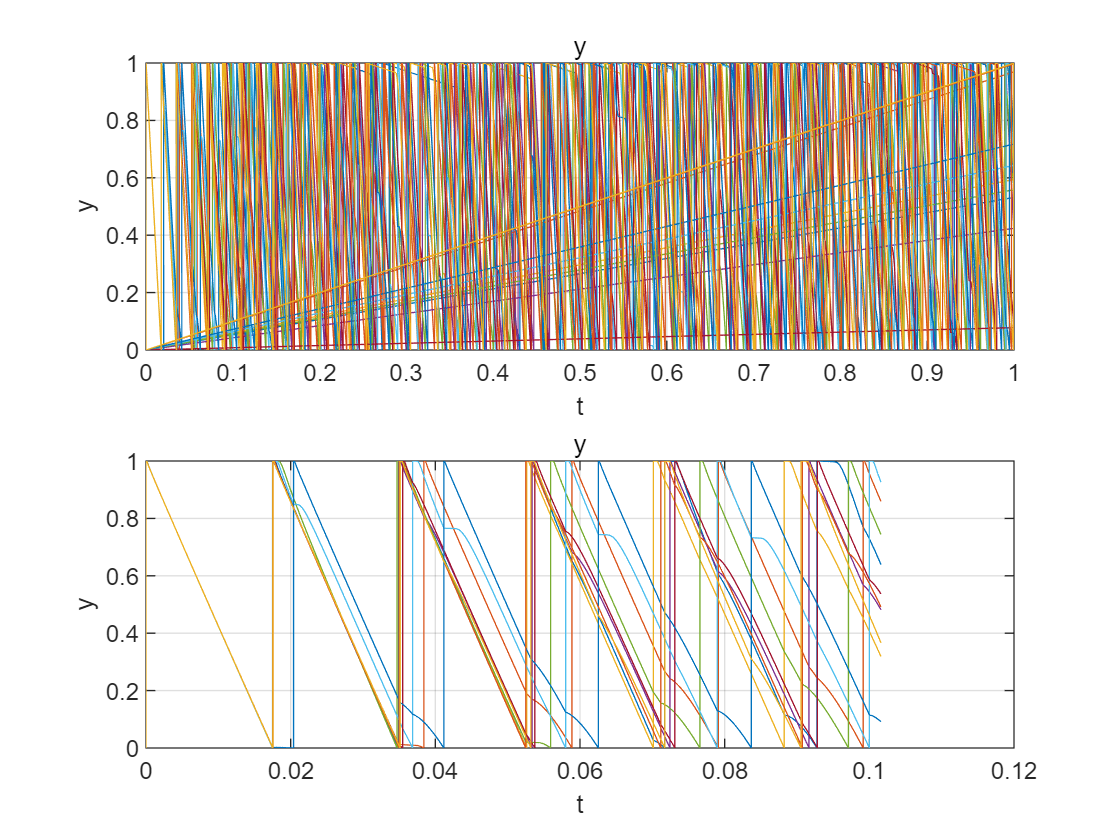


figure()

subplot(2,1,1)
plot(tout(1:end),sout(1:end,41:end))
title("y")
xlabel('t')
ylabel('y')
grid on

subplot(2,1,2)
plot(tout(1:500),sout(1:500,41:end))
title("y")
xlabel('t')
ylabel('y')
grid on

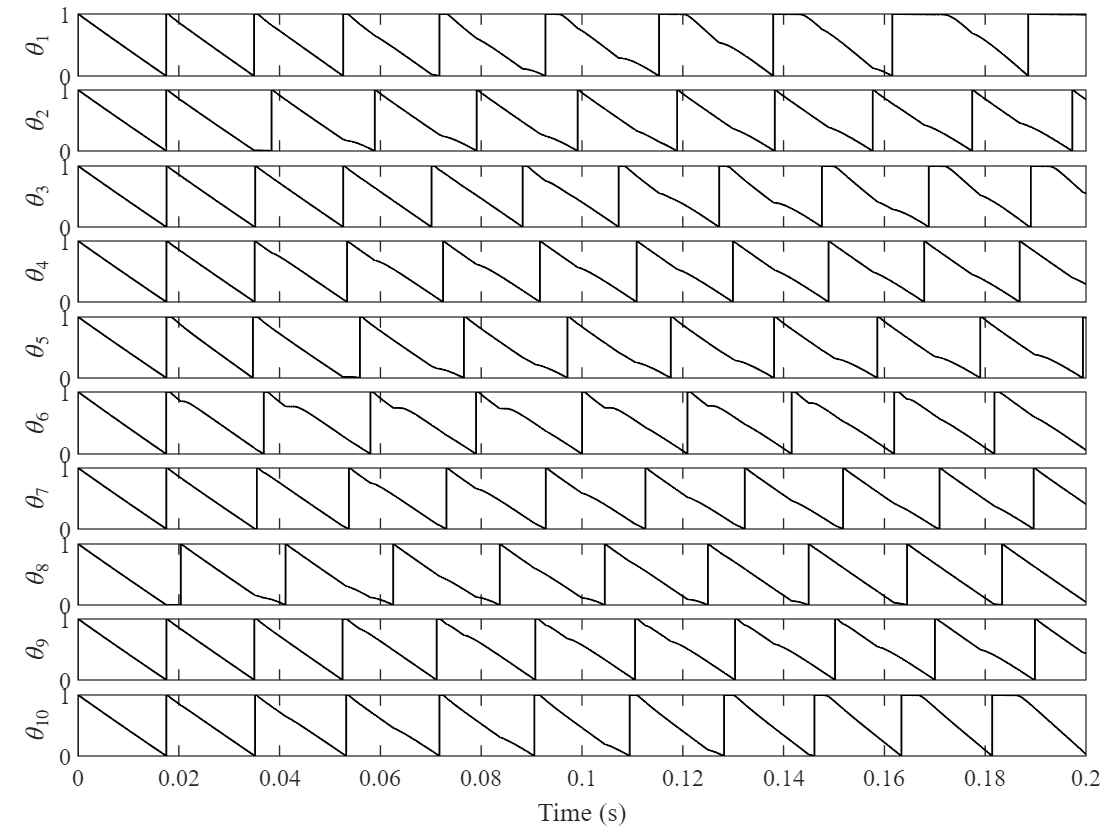

figure()
y_history = sout(:,41:end)';
ywidth = 0.090;
for i = 1:10
subplot(10,1,i)
plot(tout(1:1500), y_history(i,1:1500),'LineWidth',0.7,'Color','black')
set(gca,'xlim',[0 0.2]);
if i ~= 10
set(gca,'xticklabel',[]);
end
set(gca,'ytick',[0 1]);
set(gca,'position',[0.07 1-ywidth*i 0.9 ywidth*0.81])
set(gca, 'Fontname', 'Times New Roman', 'Fontsize',9)
ylabel('$\theta_{'+string(i)+'}$','interpreter','latex')
hold on
end
grid off
xlabel("Time (s)")

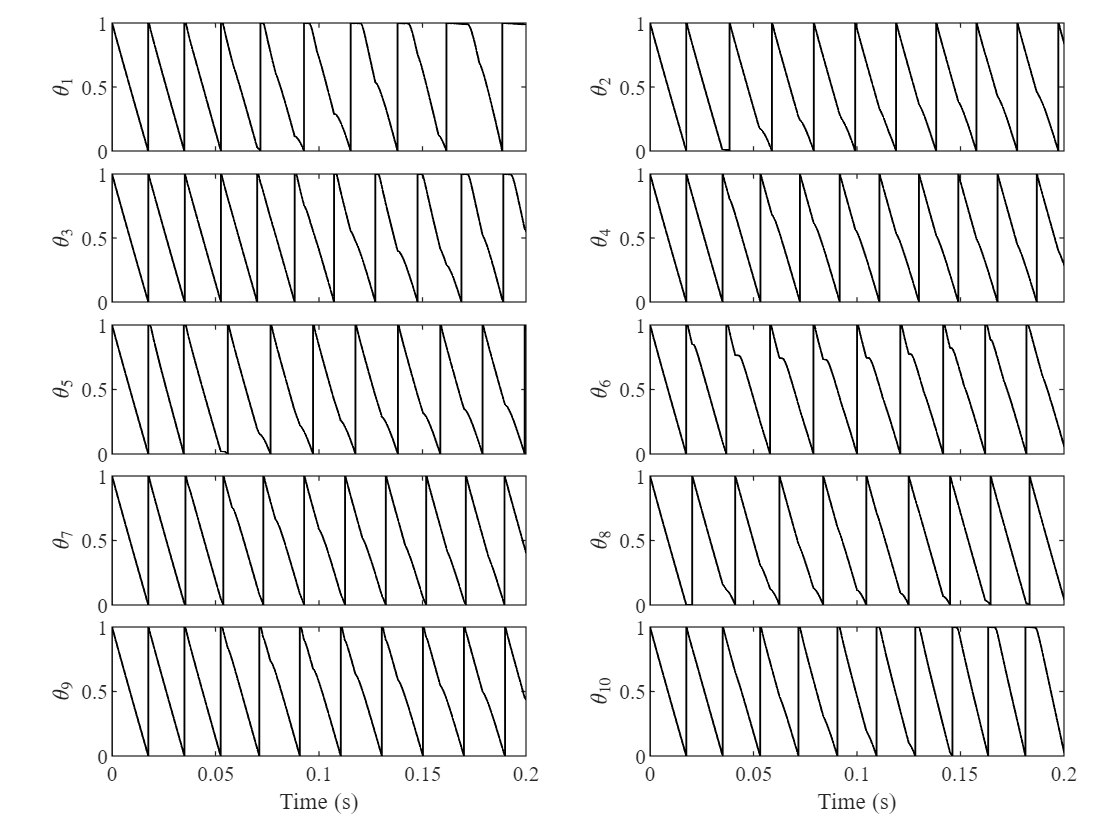

figure()
ywidth = 0.18;
for i = 1:10
subplot(5,2,i)
plot(tout(1:1500), y_history(i,1:1500),'LineWidth',0.7,'Color','black')
set(gca,'xlim',[0 0.2]);
if i ~= 9 && i ~= 10
set(gca,'xticklabel',[]);
end
%set(gca,'ytick',[0 500 1000]);
%set(gca,'position',[0.1 1-ywidth*i 0.85 ywidth*0.83])
if mod(i,2) == 1
set(gca,'position',[0.1 1-ywidth*(floor((i-1)/2)+1) 0.37 ywidth*0.85])
else
set(gca,'position',[0.58 1-ywidth*(floor((i-1)/2)+1) 0.37 ywidth*0.85])
end
set(gca, 'Fontname', 'Times New Roman', 'Fontsize',8)
ylabel('$\theta_{'+string(i)+'}$','Interpreter','latex')
hold on

if i == 9 || i == 10
xlabel("Time (s)")
end
end

 hold off

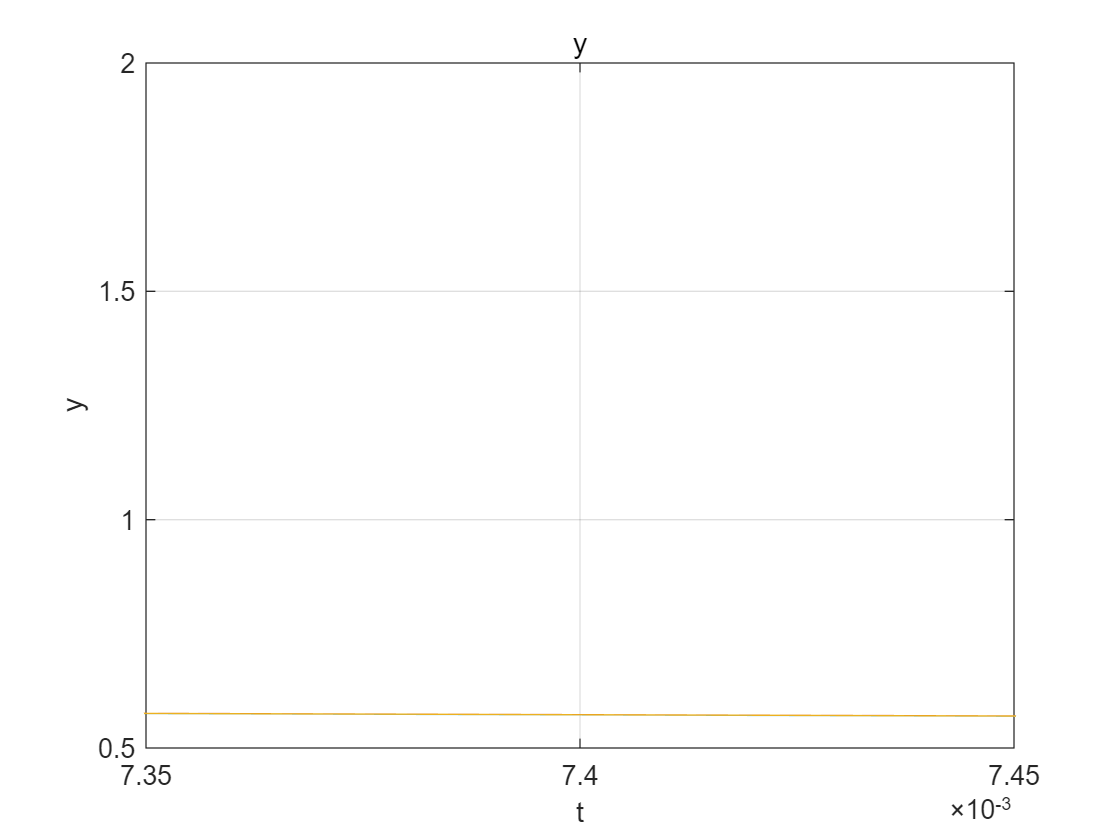


figure()
plot(tout(:),sout(:,41:end))
title("y")
xlabel('t')
ylabel('y')
xlim([0.00735 0.00745])
ylim([0.5 2])
grid on

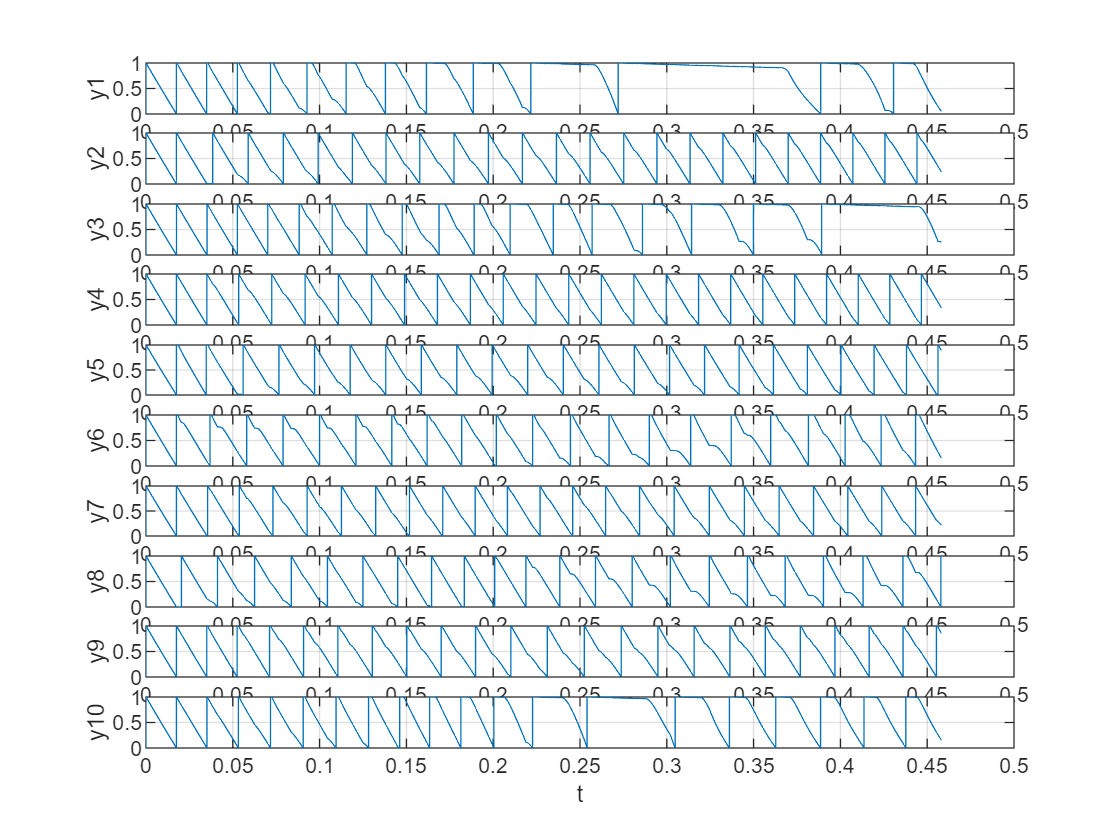


figure()
for i  = 1:10
subplot(10,1,i)
plot(tout(1:2500),sout(1:2500,40+i))
xlabel('t')
ylabel('y'+string(i))
grid on
end

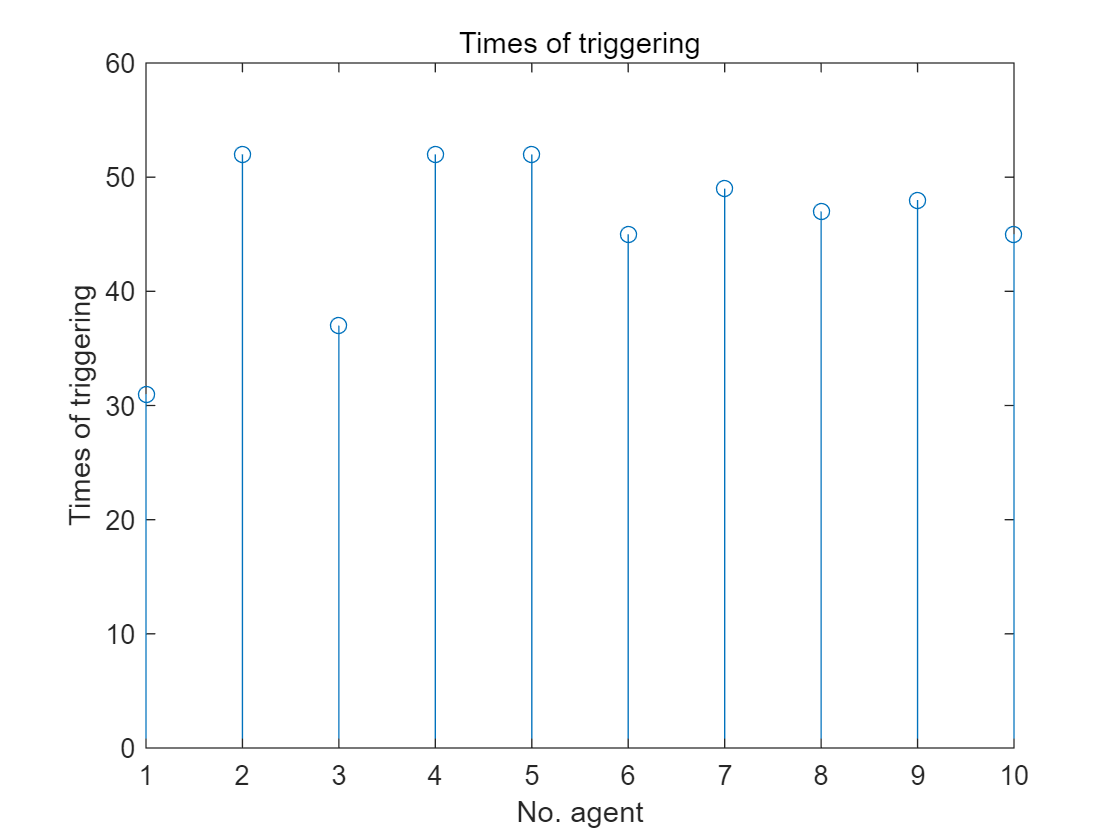

figure()
stem(times_trigger)
xlabel('No. agent')
ylabel('Times of triggering')
title("Times of triggering")

disp(tfinal/min(times_trigger)*1000)

   32.2581



disp(tfinal/max(times_trigger)*1000)

   19.2308



disp(tfinal/mean(times_trigger)*1000)

   21.8341



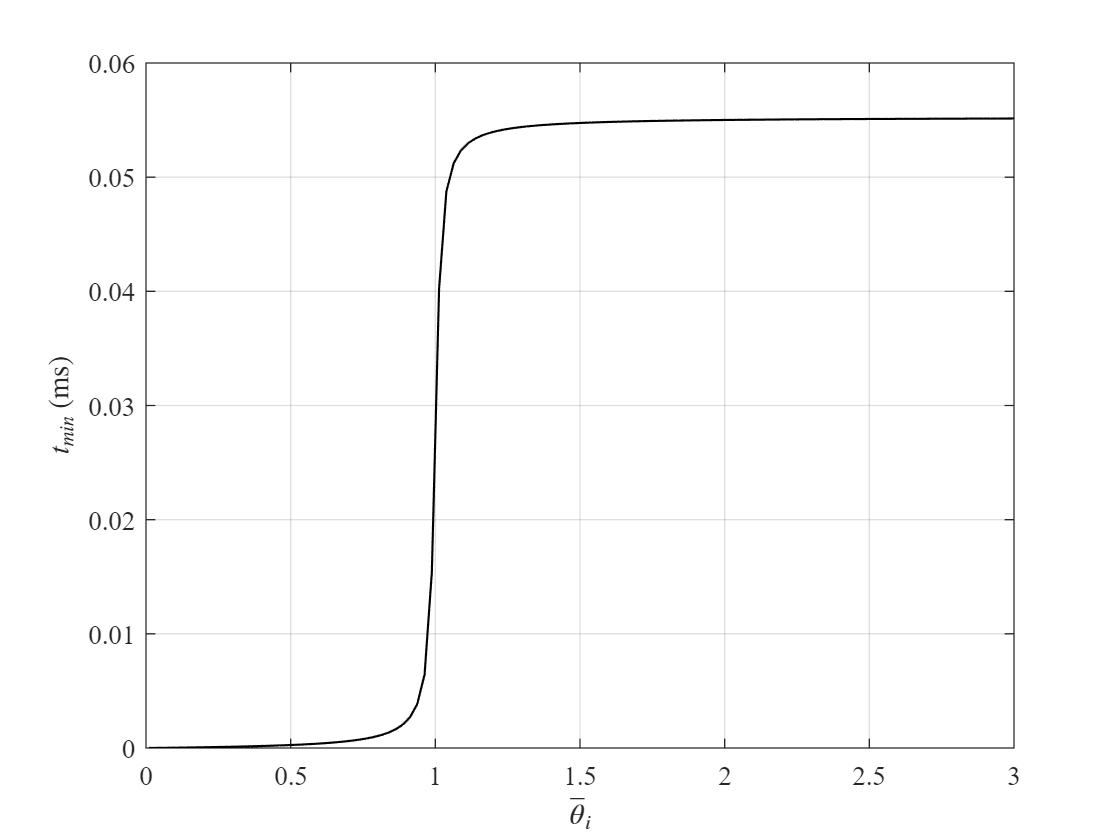

k=100;
b=delta_min/beta^2 * (1/delta_max^2-1/k);
fun = @(h) 1./( max((2*delta_max*beta+k/delta_min-delta_min)/eta+2*alpha/eta.*h+1./(eta*b).*(h-1).^2,0)  +tau);
y_bar_list = linspace(0.01,5,200);
tmin_list = [];
for yi = y_bar_list
    tmin_list = [tmin_list integral(fun,0,yi)];
end
plot(y_bar_list,tmin_list*1000,'Color','black','LineWidth',0.8)
xlabel('$\bar{\theta}_i$','interpreter','latex')
ylabel('$t_{min}$ (ms)','interpreter','latex')
set(gca, 'Fontname', 'Times New Roman', 'Fontsize',10)
xlim([0 3])
grid on

function dxdt = DETM_dynamic(t,x)

    global A B K H1 alpha delta beta eta epsilon tau
    
    xi = x(1:20);
    e = x(21:40);
    y = x(41:50);
    
    z = -kron(H1, eye(2))*(e+xi);
    
    dxidt = (kron(eye(10),A)-kron(H1,B*K))*xi - kron(H1, B*K)*e;
    dedt = kron(H1,B*K)*xi +(kron(eye(10),A)+kron(H1,B*K))*e;
    dydt = zeros(10,1);
    
    for i = 1:10
        ei = e(2*i-1 : 2*i);
        zi = z(2*i-1 : 2*i);
        if norm(ei) > 0
            gamma = -(2*alpha*y(i)+2*delta*beta + (y(i)-1)^2)*(ei')*ei / (eta*(ei')*ei+zi'*zi) ...
                        - (2*epsilon*y(i)+beta^2)*(zi')*zi / (eta*(ei')*ei+zi'*zi);
            gamma = min([gamma 0]);
        else
            gamma = 0;
        end
        dydt(i) = gamma-tau;
    end
    
    dxdt = [dxidt; dedt; dydt];

end

function dxdt = DETM2_dynamic(t,x)  % V=V1+V2

    global A B K H1 alpha delta beta eta epsilon tau delta_max P
    
    xi = x(1:20);
    e = x(21:40);
    y = x(41:50);
    
    z = -kron(H1, eye(2))*(e+xi);
    
    dxidt = (kron(eye(10),A)-kron(H1,B*K))*xi - kron(H1, B*K)*e;
    dedt = kron(H1,B*K)*xi +(kron(eye(10),A)+kron(H1,B*K))*e;
    dydt = zeros(10,1);
    
    for i = 1:10
        ei = e(2*i-1 : 2*i);
        zi = z(2*i-1 : 2*i);
        if norm(ei) > 0
            gamma = -(2*delta_max*beta+2*alpha*y(i))/eta + 2*y(i)*ei'*P*(B*B')*P*zi/(eta*(ei'*ei)) - 2*zi'*P*(B*B')*P*ei/(eta*(ei'*ei));
            gamma = min([gamma 0]);
        else
            gamma = 0;
        end
        dydt(i) = gamma-tau;
    end
    
    dxdt = [dxidt; dedt; dydt];

end

function dxdt = DETM3_dynamic(t,x)  % V=V1+V2, new

    global A B K H1 alpha delta beta eta epsilon tau delta_max delta_min P
    M1 = P*B*B'*P;
    M2 = P*A+A'*P;
    xi = x(1:20);
    e = x(21:40);
    y = x(41:50);
    
    z = -kron(H1, eye(2))*(e+xi);
    
    dxidt = (kron(eye(10),A)-kron(H1,B*K))*xi - kron(H1, B*K)*e;
    dedt = kron(H1,B*K)*xi +(kron(eye(10),A)+kron(H1,B*K))*e;
    dydt = zeros(10,1);
    
    k = 100;
    for i = 1:10
        ei = e(2*i-1 : 2*i);
        zi = z(2*i-1 : 2*i);
        if norm(ei) > 0
            gamma = - ((k/delta_min-delta_min)*(ei'*ei)+ei'*(2*delta_max*M1+y(i)*M2)*ei)/(ei'*P*ei) - 2*(1-y(i))*ei'*P*(B*B')*P*zi/(ei'*P*ei) - delta_min*(1/k-1/delta_max^2)*(zi'*zi)/(ei'*P*ei);
            gamma = min([gamma 0]);
        else
            gamma = 0;
        end
        dydt(i) = gamma-tau;
    end
    
    dxdt = [dxidt; dedt; dydt];

end

function [value,isterminal,direction] = DETM_events(t,x)

    value = min(x(41:end)) + abs(min(x(41:end)));
    isterminal = 1;
    direction = [];

end